## **07/03/2025**

**LEZIONE 1**

**Variabili**

x = 1;
y = x + 3;
z = x + y

**Stringa**

a = "prova1";
% Esempio di commento su singola linea

%{
^ non posso scrivere su questa linea
commento multilinea

x

%}

b = "ciao"

**For**

for i = 50:-1:0
    i
end

i = 50

i = 49

i = 48

i = 47

i = 46

i = 45

i = 44

i = 43

i = 42

i = 41

i = 40

i = 39

i = 38

i = 37

i = 36

i = 35

i = 34

i = 33

i = 32

i = 31

i = 30

i = 29

i = 28

i = 27

i = 26

i = 25

i = 24

i = 23

i = 22

i = 21

i = 20

i = 19

i = 18

i = 17

i = 16

i = 15

i = 14

i = 13

i = 12

i = 11

i = 10

i = 9

i = 8

i = 7

i = 6

i = 5

i = 4

i = 3

i = 2

i = 1

i = 0

**Calcoli**

z = x + y;

x = 0.1000

y = 1

z = 1.1000

z = x - y;
z = x / y;
z = x * y;
z = mod (x, 352);
z = pow2(x, y);

**Condizioni**

if x < y
    %corpo costrutto
    z
end

%il not
if x ~= y
    %corpo if

    %uguaglianza
elseif x == y
    %corpo elseif

else
    %corpo else
end

**Switch**

switch x
    case 1
        x
    case 2
        x = x + 1;
    otherwise
        disp(x)
end

**Print**

x - y

%equivalente del printf
disp("il valore di x è")
disp(x)

%oppure
fprintf("il valore di y è %f", y)

**Input**

disp("Inserisci il valore di a: ")
a = input("");
disp(a)

**ESERCIZIO 1**

**prendere in input una stringa che rappresenta il piatto del menu**

**in base al piatto scelto si stampa il prezzo**

**MENU**

primo = 5.8;
secondo = 6.9;
poto = 957.0;
laMinghia = 69.96;
costrutto = 9.3;

piatto = "";

**CODICE**


piatto = input("inserisci il nome del piatto scelto: ", "s");

switch piatto
    case "primo"
        fprintf ("il piatto costa %.2f", primo)
    case "secondo"
        fprintf ("il piatto costa %.2f", secondo)
    case "poto"
        fprintf ("il piatto costa %.2f", poto)
    case "laMinghia"
        fprintf ("il piatto costa %.2f", laMinghia)        
    case "strunzo"
        fprintf ("il piatto costa %2.f", costrutto)        
    otherwise
        disp("il piatto non esiste")
end

## **14/03/2025**

**LEZIONE 2**

format permette di modificare la rappresentazione dei numeri preimpostati da matlab, come pi, i ecc

e.g.

format short    //permette di vedere il numero in formato short

format shortE    //permette di vedere in formato short in notazione scientifica

il comando fix "TRONCA" il numero decimale

e.g.

fix(pi)    //restituisce: 3

**FLOOR(x),  CEIL(x) e ROUND(x, n, type)**

floor arrotonda per difetto        //floor(pi) = 3

ceil arrotonda per eccesso        //ceil(pi) = 4

round arrotonda bene

    x = valore da arrotondare

    n = numero di cifre decimali

    type = tipo di arrotondamento

        e.g.

            pi = 3.141596..

            x = 0.00000000012447

            round(pi) = 3

            round(pi, 4) = 3.1416

            round(x, 2, 'significant') = 1.2

**ERRORE ASSOLUTO E RELATIVO**

l'arrotondamento porta a perdita di informazioni

la differenza tra il numero arrotondato e quello non si può calcolare tramite l'errore assoluto:

e.g.

    pi = 3.141..

    pi2 = round(pi, 10, 'significant')

l'errore assoluto è:

    errAbs = abs(pi-pi2)

l'errore relativo è:

    errRel = errAbs / abs(pi)

**CICLI:**

while e for (e basta)

for i = 0 : 1 : 100
    %corpo
end

    i = indice

    assegnazione :

    step :

    condizione finale

in C sarebbe quindi

    for(int i = 0; i <= 100; i++){

        //incremento e condizione si invertono

    }

for i = 0 : -1 : -20
    x = 10^-i;

    f1 = (1 - cos(x)) / x^2;
    f2 = 1/2 * ((sin(x/2)) / (x/2)) ^ 2;

    pause
end

pause sarebbe come il getchar()

keyboard serve per il debug

x = 10;
while (x > 10)
    x = x-1;
end

**EPSILON MACHINA = 2.220446049250313e-16**

il numero più piccolo che sommato ad 1 ci da un numero diverso da 1

ep = 1;
flagRipeti = true;
k = 0;
while (flagRipeti)
    ep = ep/2;
    x = 1+ep;
    flagRipeti = (x > 1);
    k = k+1;
end

ep = ep * 2;    %epsilon machina trovato da noi
%va raddoppiato perchè il codice dimezza l'epsilon facendolo due volte

**ESERCIZIO**

input a, b, c

clear
clc

% SUGGERIMENTO: Per vedere l'effetto dell'errore numerico, prova a inserire 
% valori come: a = 100, b = 0.1, c = 100
disp('--- Dimostrazione perdita di associatività ---')

--- Dimostrazione perdita di associatività ---


a = input("Input di a: ");
b = input("Input di b: ");
c = input("Input di c: ");

% Arrotondare i valori di a, b e c (Simulazione macchina a 3 cifre)
aR = round(a, 3, "significant");
bR = round(b, 3, "significant");
cR = round(c, 3, "significant");

% Valore esatto di riferimento (calcolato alla massima precisione di MATLAB)
val_esatto1 = (a+b)-c;
val_esatto2 = a+(b-c);

% Caso 1: x1 = (a+b)-c
x1 = round((aR+bR), 3, "significant");
x1 = round((x1-cR), 3, "significant");

% Caso 2: x2 = a+(b-c)
x2 = round((bR - cR), 3, "significant");
x2 = round((aR+x2), 3, "significant"); % CORRETTO: aR invece di a, e 3 invece di 2

% Errore assoluto
errAssX1 = abs(val_esatto1 - x1);
errAssX2 = abs(val_esatto2 - x2);

% Errore relativo
errRelX1 = errAssX1 / abs(val_esatto1);
errRelX2 = errAssX2 / abs(val_esatto2);

% --- OUTPUT DEI RISULTATI ---
fprintf('\n--- RISULTATI ---\n');


--- RISULTATI ---


fprintf('Valore "esatto": %f\n', val_esatto1);

Valore "esatto": -16.000000


fprintf('Risultato x1 = (a+b)-c : %f (Errore Relativo: %e)\n', x1, errRelX1);

Risultato x1 = (a+b)-c : -16.000000 (Errore Relativo: 0.000000e+00)


fprintf('Risultato x2 = a+(b-c) : %f (Errore Relativo: %e)\n', x2, errRelX2);

Risultato x2 = a+(b-c) : -16.000000 (Errore Relativo: 0.000000e+00)



if errRelX1 < errRelX2
    fprintf('\nConclusione: Per questi input, (a+b)-c è stato più preciso.\n');
elseif errRelX2 < errRelX1
    fprintf('\nConclusione: Per questi input, a+(b-c) è stato più preciso.\n');
else
    fprintf('\nConclusione: Entrambe le operazioni hanno restituito la stessa precisione.\n');
end


Conclusione: Entrambe le operazioni hanno restituito la stessa precisione.


## **21/03/2025**

**LEZIONE 3**

**Vettori**

vettore riga

xr = [1,2,3,4,5]

vettore colonna

xc = [1;2;3;4;5]

vettore dichiarato con gli spazi

yr = [1 2 3 4 5]

per farlo diventare vettore colonna basta mettere l'apice a fine dichiarazione per fare la matrice trasposta

yc = [1 2 3 4 5]'

**Operazioni tra vettori**

è possibile fare la somma tra vettori con '+'

res = xr + yr

stessa cosa con sottrazione '-' e la moltiplicazione '*'

ovviamente per la moltiplicazione la matrice1 di righe n e colonne m si può moltiplicare solo con un'altra matrice di righe m e colonne n

m1 = [1 2 3 4 5]
m2 = [6 7 8 9 0]'
res = m1 * m2
%oppure se m2 non è trasposta si può fare
%res = m1 + m2'

'.*' fa l'operazione elemento per elemento, quindi:

m1 = [1 2 3 4 5]
m2 = [6 7 8 9 0]
res = m1 .* m2

**Matrici**

A = [1 2 3;
     4 5 6;
     7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


Matlab memorizza solo matrici.     t = 1 è una matrice 1x1

v1 = [1 2 3]

v1 =      1     2     3


v2 = [4 5 6]

v2 =      4     5     6


v3 = [7 8 9]

v3 =      7     8     9



A2 = [v1;v2;v3]    %in questo caso posso combinare vettori 

A2 =      1     2     3
     4     5     6
     7     8     9


                   % diversi in una unica matrice

%stessa cosa con le colonne
A3 = [v1' v2' v3']

A3 =      1     4     7
     2     5     8
     3     6     9


%oppure
A4 = [v1' v2' v3']'

A4 =      1     2     3
     4     5     6
     7     8     9


ESEMPIO

combinazioni di matrici

A1 = [1 2;
      3 4]
A2 = [5 6;
      7 8]
A3 = [9 10;
      11 12]

A = [A1 A2;
     A3 A1]

**Modo casuale di generazione di matrici e vettori**

Fino ad ora abbiamo fatto in maniera esplicita, ora vediamo maniera implicita

rand    %crea un numero casuale compreso tra 0 e 1

ans = 0.8147

%help rand

per creare una matrice quadrata 3x3 casuale si fa

rand(3)

ans =     0.9058    0.6324    0.5469
    0.1270    0.0975    0.9575
    0.9134    0.2785    0.9649


per fare una matrice rettangolare e.g. 3x4 si fa

A = rand(3,4)

A =     0.1576    0.4854    0.4218    0.9595
    0.9706    0.8003    0.9157    0.6557
    0.9572    0.1419    0.7922    0.0357


creo un vettore size e posso passarlo all'interno dell'input di rand per creare una matrice casuale

sz = [3 4]

sz =      3     4


A1 = rand(sz)

A1 =     0.8491    0.7577    0.6555    0.0318
    0.9340    0.7431    0.1712    0.2769
    0.6787    0.3922    0.7060    0.0462


%oppure tramite variabili
lines = 3

lines = 3

rows = 4

rows = 4

A2 = rand(lines, rows)

A2 =     0.0971    0.3171    0.4387    0.7952
    0.8235    0.9502    0.3816    0.1869
    0.6948    0.0344    0.7655    0.4898


randn crea una matrice nxm ma i valori seguono una distribuzione normale

B = randn(lines, rows)

B =    -0.1649    1.1093   -1.2141    1.5326
    0.6277   -0.8637   -1.1135   -0.7697
    1.0933    0.0774   -0.0068    0.3714


randi genera una matrice nxm con numeri interi

%help randi
%imax = numero massimo tra cui crearlo, tra 0 e imax
%par2 = elementi del vettore o numero di righe
%par3 = num colonne
randi(10, lines, rows)

ans =      3     6    10     2
     8     7     6     3
     3     9     2     9


%per fare una matrice tra x e y (INCLUSI) si mette una matrice
randi([10, 20], lines, rows)

ans =     12    20    12    13
    18    13    16    19
    12    12    15    16


per inizializzare la matrice (porla tutta a 0) si usa zeros

%matrice quadrata
zeros(5)

ans =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


%matrice rettangolare
zeros (3, 4)

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0


%vettore riga
zeros(1, 5)

ans =      0     0     0     0     0


%vettore colonna
zeros(5, 1)

ans =      0
     0
     0
     0
     0



%matrice ecc inizializzata a 1
ones(5)

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


per creare la matrice identità si fa

eye(5)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


%ricordati che la matrice identità è solo quadrata

**Operatori**

+ somma

- sottrazione

* prodotto matriciale

.* prodotto elemento per elemento

^ potenza

.^ potenza elemento per elemento

**Operatori di confronto**

==            uguale

<              minore

>              maggiore

>= e <=   maggiore uguale e mimore uguale

**Operatore di assegnamento **=

**Accedere agli elementi di una matrice**

in C si fa A[i, j];

su matlab

i = 2

i = 2

j = 3

j = 3

A = [1 2 3 4;
     4 5 6 5;
     7 8 9 6]

A =      1     2     3     4
     4     5     6     5
     7     8     9     6



A(i, j)

ans = 6

in matlab la prima posizione dell'array e la posizione 1 e NON 0

Posso andare a prendere singole parti della mia matrice, per esempio prendere tutta la seconda e terza riga

A(2:3, :)

ans =      4     5     6     5
     7     8     9     6


%ovvero tutti gli elementi della riga dalla 2 alla 3
%l'operatore end dice fino alla fine quindi per esempio 
% dalla seconda fino all'ultima colonna
A(2 : end, :)

ans =      4     5     6     5
     7     8     9     6


il comando size restituisce il vettore delle dimensioni:

%help size
size(A)

ans =      3     4


%restituirà: righe colonne

size(A, 1)    %restituisce il numero di righe

ans = 3

size(A, 2)    %restituisce il numero di colonne

ans = 4

è possibile mofificare anche il valore di una cella della matrice

A(1, 1) = 0

A =      0     2     3     4
     4     5     6     5
     7     8     9     6


A(1, :) = 0     %tutti gli elementi della prima riga uguali a 0

A =      0     0     0     0
     4     5     6     5
     7     8     9     6


Per ottenere il **determinante** di una matrice si usa

A1 = randi(10, 5)

A1 =      6     4     8     1     6
    10     6    10     4     2
     3     1     2     2     7
     8     1     6     8     3
     8     6     5     4     7


detA1 = det(A1)

detA1 = -802.0000

Matrice inversa

A1i = A1^-1

A1i =    -1.5711    1.7406    2.0823   -0.7357   -0.9177
    0.7781   -0.9239   -1.2693    0.3167    0.7307
    0.7282   -0.6147   -0.7905    0.3092    0.2095
    0.8903   -1.1197   -1.3466    0.5835    0.6534
    0.0998   -0.1185    0.0424    0.0150    0.0424


per avere il rank della matrice si usa

rank(A1)

ans = 5

per avere la norma della matrice si usa:

norm(A)     %di default usa la norma 2

ans = 18.1913

**ESERCIZI LEZ 21/03/2025**

**1. **Creare uno script che calcola il prodotto matriciale righe per colonne AB senza usare l'operatore * (è consentito per eseguire il prodotto tra i singoli elementi delle matrici). Eseguire i controlli sulle dimensione delle matrici e stampare eventuali errori con il comando error di matlab.

function C = prodMatr(A, B)
    if(size(A,2) ~= size(B,1))
        error('Non si puo effettuare il prodotto matriciale')
    else
        dim = [size(A,1) size(B,2)];
        C = zeros(dim);
        for i = 1 : 1 : dim(1)
            for j = 1 : 1 : dim(2)
                somma = 0;
                for k = 1 : 1 : size(A, 2)
                    somma = somma + (A(i,k) * B(k, j));
                end
                C(i, j) = somma;
            end
        end
    end
end


A = [1 2 3;
     4 5 6];

B = [7 8;
     9 10;
     11 12];

res = prodMatr(A, B)

**2. **Generare un numero casuale n tra 10 e 30 finchè non è divisibile per 5. Generare una matrice quadrata di dimensione [n/5 x n/5] e popolarla con i  numeri da 1 a n/5 ordinati per riga.

n = 1;
while(mod(n, 5) ~= 0)
    n = randi([10, 30], 1, 1);
end

A = zeros(n/5, n/5);
count = 1;
n
n_div_5 = n/5
for i = 1 : 1 : n/5
    for j = 1 : 1 : n/5
        A(i,j) = count;
        count = count + 1;
    end
end

A

## **04/04/2025**

**LEZIONE 4**

**Matrici di differenti tipi;**

A = rand(5)     %matrice 5x5 randomica

Matrice triangolare:

U = triu(A)     %estrae la matrice triangolare superiore di A
L = tril(A)     %estrae la matrice triangolare inferiore di A

%matrice triangolare inferiore con diagonale = 0
%0 0 0 0
%1 0 0 0
%2 3 0 0
%4 5 6 0
diag(A)
D = diag(diag(A))     % diag = diagonale di A
                      %diag(diag) = matrice della diagonale di A
B = L - D       %matrice triang. inf. senza la diagonale

%Oppure usare:
L2 = tril(A, -1)
%con -2 ecc toglie fino alle diagonali corrispondenti
isequal(B, L2)

Matrice Simmetrica:

%creare matrice simmetrica di A
S = A * A'      %ovvero A per la sua matrice trasposta (A')
isequal(S, S')  %quando una matrice è simmetrica allora è uguale alla trasposta

issymmetric(S)  %comando per vedere se in questo caso S è simmetrica

istriu(U)       %comando per vedere se è una matrice triangolare superiore (upper)
istril(L)       %comando per vedere se è una matrice triangolare inferiore (lower)
%La matrice diagonale è sia triang. sup. che inf.
istriu(D)
istril(D)

isdiag(D)       %determina se la matrice è triangolare

Ricostruiamo la matrice A da U, L e D

if(istriu(U) && istril(L))
    Utmp = U-D;
    Ltmp = L-D;
    Atmp = Ltmp + Utmp + D
    if(isequal(A, Atmp))
        disp("A e Atmp sono uguali")
    else
        disp("A e Atmp sono diverse")
    end
end

Per verificare se una matrice è hermittiana si usa:

ishermitian(A)

Per vedere se la mia matrice è **ortogonale**:

non esiste isorth

**CREIAMO UNA FUNZIONE CHE FACCIA isorth(..)**

importiamo il file isorth.m

O = eye(5)
isorth(O)

Come trovare la soluzione di A * x = b?

A = rand(3)
b = ones(3, 1)      %vettore colonna soluzione

%come trovare il vettore soluzione x?
%x = inv(A)*b 
% oppure:
x = A\b     % NB \ è diverso da /

conviene usare A\b perchè trova il metodo più conveniente per risolvere il sistema lineare in base alla struttura della mia matrice

e.g.

- Triangolare = per sostituzione

- ecc..

A = rand(3)
if(abs(det(A) <= 1e-10))
    error("la matrice non è invertibile")
end
x_real = [1 2 3]'

b = A*x_real

x = A\b
isequal(x_real, x)      %errore numerico dato dal compilatore

**NON FARE if(det(A) == 0)...**

**Fai invece:**

if(abs(det(A) < 1e-10))
    error("la matrice non è invertibile");
end

Calcolo autovettori e autovalori:

A = rand(3)
[V, D] = eig(A)          %autovalori della matrice
%V = Autovettori
%D = Autovalori
D = diag(D)             %spettro della matrice

Cercare il raggio spettrale

rho = max(abs(D))

%oppure
d_sort = sort(abs(D), 'descend')    %descend ovvero dal più grande al più piccolo, di default è 'ascend'
rho = d_sort(1)

%oppure
%eigs: da un subset degli autovalori e autovettori, ovvero gli diciamo noi quanti ne vogliamo avere
rho = eigs(A, 1, 'largestabs');
%restituisce l'autovalore in abs più grande ma con il suo segno
% quindi tra 1 -7 6 restituisce -7
rho = abs(eigs(A, 1, 'largestabs'))    %in questo caso restituisce il valore in abs

fare dei grafici

**GENERALMENTE FARLO SU UN FILE .m NON .mlx**

x = 0:0.1:2*pi
y = sin(x)
z = cos(x)

figure;
p = plot(x, y, 'LineWidth',3, 'Color',"r", 'LineStyle','--');
title("Funzione seno")
xlabel("x")
ylabel("y(sin)")
grid on
hold on

plot(x, z, 'b:', 'LineWidth',3);


legend('sin(x)', 'cos(x)')

## **11/04/2025**

**LEZIONE 5**

Gauss:

clear
clc

err = [];
errGP = [];
errAlu = [];
errPalu = [];
i = 1;
for n = 10 : 10 : 100
    A = rand(n);
    A = A * A';
    xReal = ones(n, 1);
    b = A * xReal;

    [U, d] = gauss(A, b);
    [U_gp , d_gp] = gauss_pivot(A, b);
    [L_alu, U_alu] = alu(A);
    [L_palu, U_palu, P_palu] = palu(A);

    %Ux = b
    x_g = U\d;
    x_gp = U_gp\d_gp;

    %Ly = b;
    %Ux = y

    y = L_alu\b;
    x_alu = U_alu\y;

    %Ly = UP
    y = L_palu\(P_palu*b);
    x_palu = U_palu \ y;

    err(i) = norm(xReal - x_g) / norm(x_g);
    errGP(i) = norm(xReal - x_gp) / norm(x_gp);
    errAlu(i) = norm(xReal - x_alu) / norm(x_alu);
    errPalu(i) = norm(xReal - x_palu) / norm(x_palu);
    i = i + 1;
end
disp("la media degli errori è: " + mean(err))
disp("la media degli errori con pivoting è: " + mean(errGP))
disp("la media degli errori di ALU è: " + mean(errAlu))
disp("la media degli errori di PALU è: " + mean(errPalu))

## **04/04/2025**

**LEZIONE 6**

**Equazioni non lineari**

qualcosa su Newton

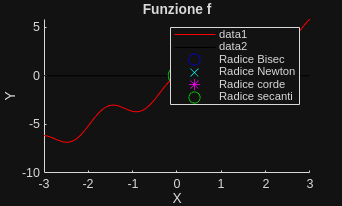

clear

clc

f = @(x) cos(4 .* x) + 2 .* x - 1;       %voglio una funzione non un valore aggiungo @(x)
fd = @(x) -4 * sin(4 .*x) + 2;
%diventa puntatore a questa funzione


%valori da plottare
x = linspace(-3, 3, 200); % crea n punti equidistaziati tra il primo e il secondo parametro
y = f(x);


%rappresentazione grafica
figure;
hold on;
plot(x, y, "-r");
plot(x, zeros(size(x)), "-k")
title("Funzione f")
xlabel("X")
ylabel("Y")
legend


[xb, yb] = bisezione(f, 0, 0.5, 1e-10, 1000);       %bisezione
[xn, kn] = newton(f, fd, 0.5, 1e-10, 100);          %metodo di newton
[xc, kc] = corde(f, fd(0.5), 0.5, 1e-10, 100);      %metodo delle corde
[xs, ks] = secanti(f, 0, 1, 1e-10, 1000);

plot(xb, f(xb), "Ob", "DisplayName", "Radice Bisec", "MarkerSize", 12);
plot(xn, f(xn), "Xc", "DisplayName", "Radice Newton", "MarkerSize", 12);
plot(xc, f(xc), "*m", "DisplayName", "Radice corde", "MarkerSize", 12);
plot(xs, f(xs), "og", "DisplayName", "Radice secanti", "MarkerSize", 12);


hold off